Function

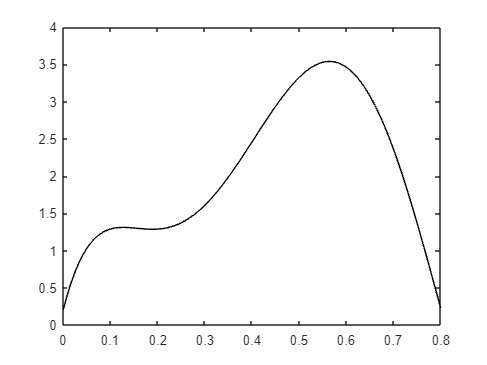

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = linspace(0, 0.8);
yy = f(xx);
plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2];
q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with simpson 1/3 rule with ns calculated from adaptive quadrature

[I_quadadapt, xpts] = quadadapt_with(f,a,b);

Error using quadadapt_with
Too many output arguments.


I_quadadapt

ypts = f(xpts);

[xpts ypts]

ns = (length(xpts)-1)/2

figure
color = ['g','y'];
for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = xpts(il:ir);
    newy = ypts(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(xpts(il),xpts(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(xpts(il:ir), ypts(il:ir),'m*')
end

plot(xx,yy,'b-')